% Load IBS data
load('D:\data\VALIDEIT09\eit\MIK_P_O\eitV2.mat');
crs = NonInvEIT(eit);

loadFilters(crs);
imgFilt = applyFilter(crs,crs.ImgRaw,crs.Fs,false);
imgFilt(isnan(imgFilt)) = 0;

load('D:\data\VALIDEIT09\eit\cct.mat');

t = crs.T;

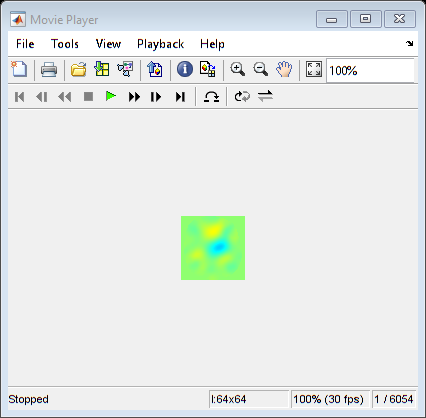

playVideo(imgFilt);

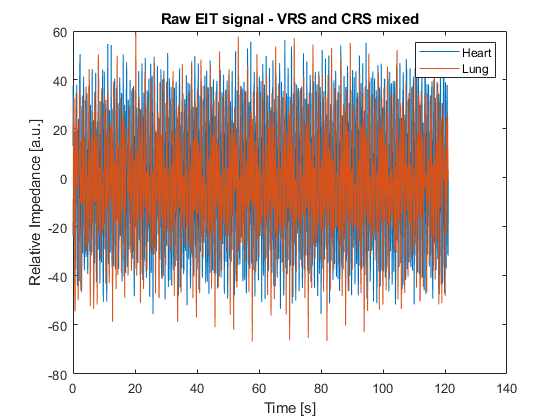

heartPix = [16,30];
lungPix = [30,40];

heartSig = squeeze(imgFilt(heartPix(1),heartPix(2),:));
lungSig = squeeze(imgFilt(lungPix(1),lungPix(2),:));

figure; plot(t, [heartSig,lungSig]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart","Lung"]);
title("Raw EIT signal - VRS and CRS mixed");

[~,mask] = spatialDenoise(imgFilt); mask(isnan(mask)) = 0;
flatIdx = find(ones(64,64));%find(mask);
[idxX,idxY] = ind2sub([size(mask,1),size(mask,2)],flatIdx);
imgIdx = [idxX,idxY];

% Initialize DMD class and properties
dmd = DMD();
rank = -1;
halfLife = 0.5;
rho = 2 ^ (- 1 / (halfLife * crs.Fs));
del = 100; % ms
nDel = floor(del * crs.Fs / 1000);

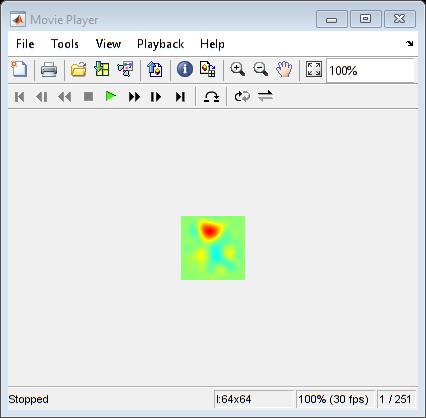

ans =   UnifiedScope with properties:

    InstanceNumber: 5
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.WorkspaceSource]
            Parent: [1×1 Figure]


% INITIALIZATION
wInit = 5; % s
nWInit = wInit * crs.Fs;

tStart = 0; nStartInit = floor(tStart * crs.Fs + 1);
nEndInit = nStartInit + nWInit + nDel;

data = imgFilt(:,:,nStartInit:nEndInit);
flatImg = reshape(data,size(data,1) * size(data,2), []);

predHor = nWInit + 1;

% X = flatImg(flatIdx,1:end-1);
% Y = flatImg(flatIdx,2:end);

X = hankelTransform(dmd,flatImg(flatIdx,1:end-1), nWInit, nDel);
Y = hankelTransform(dmd,flatImg(flatIdx,2:end), nWInit, nDel);

% X = applyHankel(flatImg(flatIdx,1:end-1), nWInit, nDel);
% Y = applyHankel(flatImg(flatIdx,2:end), nWInit, nDel);

fitKoopman(dmd, X, Y, rank, predHor, 'stream');
fitModes(dmd, X, Y, crs.Fs, 'vanilla');

[Xcomps, Xtotal] = reconData(dmd, [X,Y(:,end)], 'stream');
cleanModes(dmd);
interpModes(dmd,true);

flatImgRecon = zeros(size(flatImg,1),size(Xtotal,2));
flatImgRecon(flatIdx,:,:) = Xtotal(1:length(flatIdx),:);
XtotalImg = reshape(real(flatImgRecon),64,64,[]);

playVideo(XtotalImg)

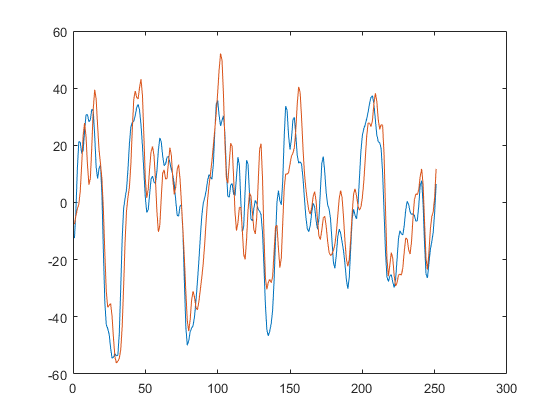

lung = squeeze(data(lungPix(1),lungPix(2),nDel+1:end));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot(lung); hold on; plot([lungRecon])

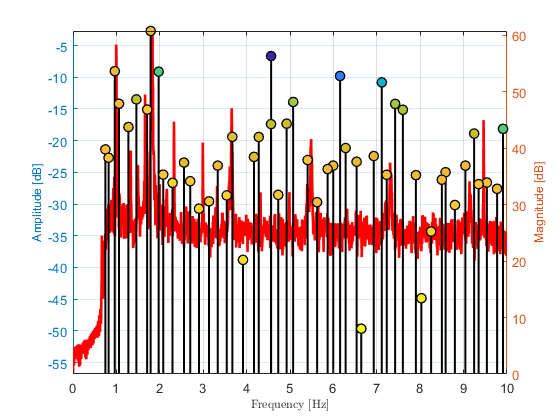

% Corrected frequency plot
powSpect(dmd, reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), [])', crs.Fs);

% Ventilation component
ffV = 0.33;                     % fundamental frequency in Hz
nHV = 10;                       % total number of harmonics
fV = ffV * (0:nHV - 1)'         % all harmonic frequencies

fV =          0
    0.3300
    0.6600
    0.9900
    1.3200
    1.6500
    1.9800
    2.3100
    2.6400
    2.9700


% Perfusion component
ffP = 1.85;                     % fundamental frequency in Hz
nHP = 3;                        % total number of harmonics
fP = ffP * (1:nHP)'             % all harmonic frequencies

fP =     1.8500
    3.7000
    5.5500


% Intermodulation component
fI = [ffP - ffV,ffV + ffP]'    % all harmonic frequencies (according to ISBN 9780367023782)

fI =     1.5200
    2.1800


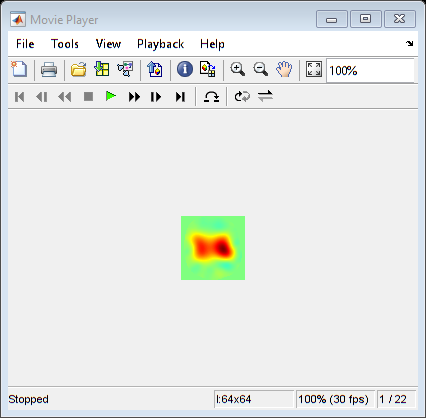


fComps = {fP;fV};

identComps(dmd, fComps);
[Xcomps, Xfinal] = reconData(dmd, [X,Y(:,end)], 'stream');

ventImgRecon = zeros(size(flatImg,1),size(Xtotal,2));
ventImgRecon(flatIdx,:,:) = Xcomps{2}(1:length(flatIdx),:);
VenttotalImg = reshape(real(ventImgRecon),64,64,[]);

PhiVent = dmd.Phi(:,flipud(dmd.ModeIdx(:,2)));
PhiVent = PhiVent(1:4096,:);
playVideo(real(reshape(PhiVent,64,64,[])));

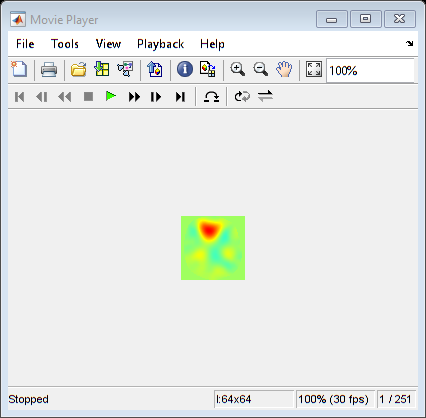

ans =   UnifiedScope with properties:

    InstanceNumber: 7
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.WorkspaceSource]
            Parent: [1×1 Figure]



playVideo(VenttotalImg)

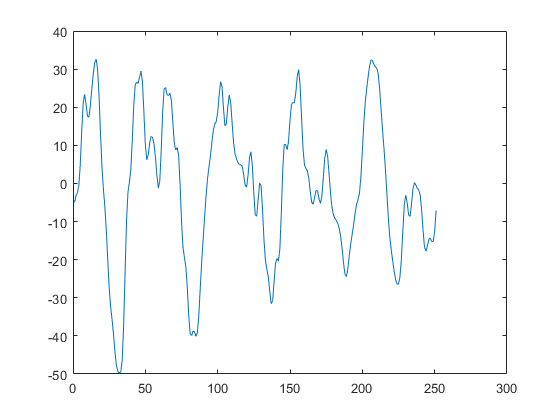

ventRecon = squeeze(VenttotalImg(lungPix(1),lungPix(2),:));
figure; plot(ventRecon);

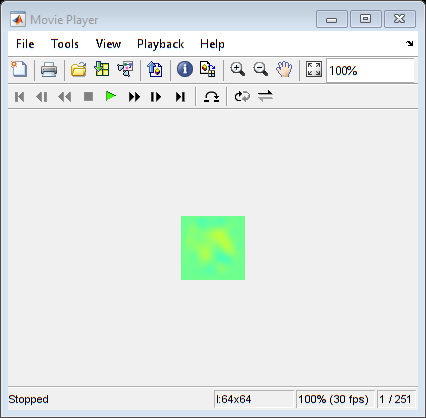

ans =   UnifiedScope with properties:

    InstanceNumber: 8
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.WorkspaceSource]
            Parent: [1×1 Figure]



perfImgRecon = zeros(size(flatImg,1),size(Xtotal,2));
perfImgRecon(flatIdx,:,:) = Xcomps{1}(1:length(flatIdx),:);
PerftotalImg = reshape(real(perfImgRecon),64,64,[]);

playVideo(PerftotalImg)

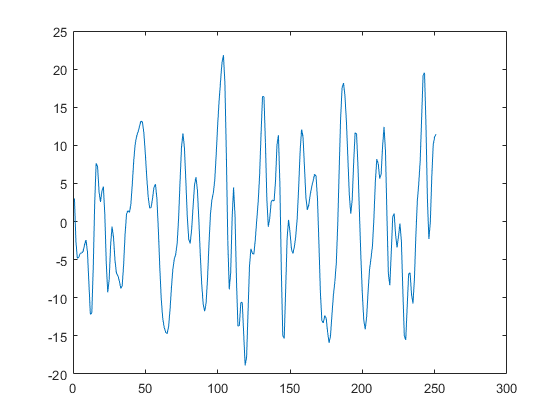

perfRecon = squeeze(PerftotalImg(lungPix(1),lungPix(2),:));
figure; plot(perfRecon);

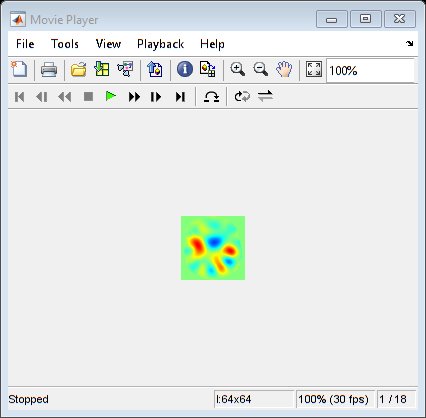

PhiPerf = dmd.Phi(:,flipud(dmd.ModeIdx(:,1)));
PhiPerf = PhiPerf(1:4096,:);
playVideo(real(reshape(PhiPerf,64,64,[])));

% Test one update
%% CREATE WINDOWS
w = 1.5; % s 
nW = floor(w * crs.Fs);
nSlideWin = nW + nDel;

predHor = nSlideWin + 1;

flatImg = reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), []);

nStart = nEndInit - nSlideWin + 1; 
nEnd = size(imgFilt,3) - nSlideWin;

windows = applyWindow(flatImg(flatIdx,:),nStart,nEnd,nSlideWin);

%% SLIDING WINDOW
Xfinal = zeros(size(flatImg,1),nSlideWin - nDel + 1);

Xnew = hankelTransform(dmd,windows(:,:,1), nW, nDel);
Ynew = hankelTransform(dmd,windows(:,:,2), nW, nDel);

% Xnew = applyHankel(windows(:,:,1), nWin, nDel);
% Ynew = applyHankel(windows(:,:,2), nWin, nDel);

tic
updateStream(dmd, Xnew, Ynew, rho);
% fitKoopman(dmd, Xnew, Ynew, rank, predHor, 'stream');
toc

Elapsed time is 0.462958 seconds.



fitModes(dmd, Xnew, Ynew, crs.Fs, 'vanilla');
[~, Xtotal] = reconData(dmd, [Xnew,Ynew(:,end)], 'stream'); 

The logical indices in position 2 contain a true value outside of the array bounds.

Error in DMD/reconData (line 339)
                           Xcomps{c} = obj.Uy(:,idx) * obj.Atilde(idx,idx) * obj.Ux(:,idx)' * X; 


Xfinal(flatIdx,:) = Xtotal(1:length(flatIdx),:);
XtotalImg = reshape(real(Xfinal),64,64,[]);
playVideo(XtotalImg);
windowFull = zeros(size(flatImg,1),size(windows,2)+1);
windowFull(flatIdx,:) = [windows(:,:,1),windows(:,end,2)];
windowFull = reshape(windowFull,64,64,[]);
lung = squeeze(windowFull(lungPix(1),lungPix(2),:));

lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot([lung(nDel+1:end)]); hold on; plot([lungRecon])
% Corrected frequency plot
cleanModes(dmd);
interpModes(dmd,true);
powSpect(dmd, reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), [])', crs.Fs);

## Harmonic Clustering

% Ventilation component
ffV = 0.33;                     % fundamental frequency in Hz
nHV = 10;                       % total number of harmonics
fV = ffV * (0:nHV - 1)'         % all harmonic frequencies
% Perfusion component
ffP = 1.85;                     % fundamental frequency in Hz
nHP = 5;                        % total number of harmonics
fP = ffP * (1:nHP)'             % all harmonic frequencies
% Intermodulation component
fI = [ffP - ffV,ffV + ffP]'    % all harmonic frequencies (according to ISBN 9780367023782)

f = {fV;fP;fI};

cleanModes(dmd);
interpModes(dmd);

% tol = 0.1; % Hz

nComps = length(f);
modeIdx = zeros(dmd.Rank,nComps);
for c = 1:nComps
    fC = f{c};
    for i = 1:length(fC)
        freqRef = fC(i);
        tol = 0.1;
        freqRange = [freqRef - tol, freqRef + tol];
        for j = 1:dmd.Rank
            freqMode = dmd.Freqs(j);
            if freqMode > freqRange(1) && freqMode < freqRange(2)
                modeIdx(j,c) = 1;
            end
        end
    end
end

%%% FULL WORKFLOW

%% INITIALIZE DMD CLASS AND PROPERTIES
dmd = DMD();
rank = -1;
halfLife = 5;
rho = 2 ^ (- 1 / (halfLife * crs.Fs));
del = 100; % ms
nDel = floor(del * crs.Fs / 1000);

%5 INITIALIZATION OF ONLINE DMD
wInit = 5; % s
tStart = 10; nStartInit = floor(tStart * crs.Fs + 1);
tEnd = wInit + tStart; nEndInit = ceil(tEnd * crs.Fs);

data = imgFilt(:,:,nStartInit:nEndInit);
flatImg = reshape(data,size(data,1) * size(data,2), []);

predHor = size(data,3)+1;

X = hankelTransform(dmd,flatImg(flatIdx,1:end-1), nDel);
Y = hankelTransform(dmd,flatImg(flatIdx,2:end), nDel);

fitKoopman(dmd, X, Y, rank, predHor, 'stream');
fitModes(dmd, X, Y, crs.Fs, 'vanilla');

%% CREATE WINDOWS
w = 1; % s 
nW = floor(w * crs.Fs);

flatImg = reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), []);

nStart = nEndInit - nW + 1; 
nEnd = size(imgFilt,3) - nW;

windows = applyWindow(flatImg(flatIdx,:,:),nStart,nEnd,nW);

%% SLIDING WINDOW
Xfinal = zeros(size(flatImg,1),size(windows,3));
compTime = zeros(size(windows,3),1);
for i = 1:500 % size(windows,3)
    Xnew = hankelTransform(dmd,windows(:,:,i), nDel);
    Ynew = hankelTransform(dmd,windows(:,:,i + 1), nDel);
    
    tic
    updateStream(dmd, Xnew, Ynew, rho);
    compTime(i) = toc;
    
    fitModes(dmd, X, Y, crs.Fs, 'vanilla');
    [~, Xtotal] = reconData(dmd, nW); 
    
    Xfinal(flatIdx,i) = Xtotal(1:length(flatIdx));
end

XtotalImg = reshape(real(Xfinal),64,64,[]);
playVideo(XtotalImg);
lung = squeeze(imgFilt(lungPix(1),lungPix(2),nStart:nEnd));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot([lung, lungRecon])

nWin = 100;
nDel = 10;
nSlideWin = nWin + nDel;

Xfull = reshape(imgFilt,64*64,[]);
windows = applyWindow(Xfull(flatIdx,:),1,1000,nSlideWin);

window = squeeze(windows(:,:,1));
tic
X = applyHankel(window, nWin, nDel);
toc

figure;
for d = 1:nDel + 1
    plot(X(nStates * (d - 1) + 1,:)); hold on;
end

function x = applyWindow(y,nStart,nEnd,nW)
    x = zeros(size(y,1),nW,nEnd - nStart);
    wCount = 1;
    for i = nStart:nEnd
        x(:,:,wCount) = y(:,i:i + nW - 1);
        wCount = wCount + 1;
    end
end

function Xout = applyHankel(window, nWin, nDel)
    nStates = size(window,1);
    nRows = (nDel + 1) * nStates;
    nCols = nWin;
    
    Xout = zeros(nRows,nCols);
    for col = 1:nCols
        count = col - 1;
        for row = 1:nDel + 1
            startState = nStates * (row - 1) + 1; 
            endState = startState + nStates - 1;
            
            Xout(startState:endState,end - col + 1) = window(:,size(window,2) - count);
            
            count = count + 1;
        end
    end
end